% Load Variables
cam = webcam(1);
net1 = load("DirtyValidNet.mat")
net2 = load("trainedResNetDirty.mat")

% Capture Data 
x = 50; % set to arbitrarily large number 
data = cell(1,x);
i = 1;
transmissionOn = true;
timerStarted=false;

 while transmissionOn 
    img = snapshot(cam);
    if (timerStarted==false)
        tic;
    end
    toc;
    
    C = semanticseg(img,net1.DirtyValidNet);
    featureMap = (C=='Frame');
    framePercentage  = (sum(featureMap(:))/(640*480))*100
    
    if framePercentage >= 5
        if timerStarted==false
            timerStarted = true;
        end
        
        data{i} = img;
        pause(3-(toc-3*(i-1))) % pause for one second
        toc
        i = i + 1
         
     elseif i > 1
        transmissionOn = false;
    end 
 end

Elapsed time is 0.000255 seconds.


framePercentage = 0

Elapsed time is 0.000025 seconds.


framePercentage = 0

Elapsed time is 0.000058 seconds.


framePercentage = 0

Elapsed time is 0.000044 seconds.


framePercentage = 0

Elapsed time is 0.000111 seconds.


framePercentage = 0

Elapsed time is 0.000007 seconds.


framePercentage = 0

Elapsed time is 0.000002 seconds.


framePercentage = 0

Elapsed time is 0.000002 seconds.


framePercentage = 0

Elapsed time is 0.000004 seconds.


framePercentage = 25.0127

Elapsed time is 3.006992 seconds.


i = 2

Elapsed time is 3.021265 seconds.


framePercentage = 25.1400

Elapsed time is 6.009967 seconds.


i = 3

Elapsed time is 6.019692 seconds.


framePercentage = 25.2103

Elapsed time is 9.004874 seconds.


i = 4

Elapsed time is 9.017966 seconds.


framePercentage = 25.2480

Elapsed time is 12.000174 seconds.


i = 5

Elapsed time is 12.010920 seconds.


framePercentage = 25.2624

Elapsed time is 15.002458 seconds.


i = 6

Elapsed time is 15.008206 seconds.


framePercentage = 25.1930

Elapsed time is 18.000430 seconds.


i = 7

Elapsed time is 18.011919 seconds.


framePercentage = 25.2025

Elapsed time is 21.004468 seconds.


i = 8

Elapsed time is 21.013544 seconds.


framePercentage = 25.2148

Elapsed time is 24.003461 seconds.


i = 9

Elapsed time is 24.008661 seconds.


framePercentage = 25.1416

Elapsed time is 27.007713 seconds.


i = 10

Elapsed time is 27.014524 seconds.


framePercentage = 25.2246

Elapsed time is 30.007814 seconds.


i = 11

Elapsed time is 30.016756 seconds.


framePercentage = 24.8701

Elapsed time is 33.004286 seconds.


i = 12

Elapsed time is 33.008614 seconds.


framePercentage = 24.4264

Elapsed time is 36.007953 seconds.


i = 13

Elapsed time is 36.016626 seconds.


framePercentage = 0

% CSK demodulation 
receivedBitStreamML = demodML(data,i,net1.DirtyValidNet,net2.trainedNet,20)

receivedBitStreamML = "05064145000501603366514530670040016705643006714031071147100405003366755310067546100501503100011131063145334701653446056310067546100515503107115433661553100441573306654534606410304744400466456010040562350641653440010333667141334001043367455431006410100014611500015133400157312710403466056030060563100611711005155134400101344701503507104020667556300670400106757133060451030050150044155734074560300635503500015431073573100605703100014330060557316645573160014133166140336731453440016430060440357675703316005710041145100615653466244035067440306641453066544035064145030051433367016134464547320700403314016126014613016506414173644067714260662141514204020137156361441067001441017531070431302735631006315734400171336705621006155735267164344744403046054633671145100601573566715433660544300671471006756210071145300645733506115031470574300671470300516430064573100665701006055736200157350641453442010034467552310615641004356535060556304625723160014500467557306071150240641025064151346201503

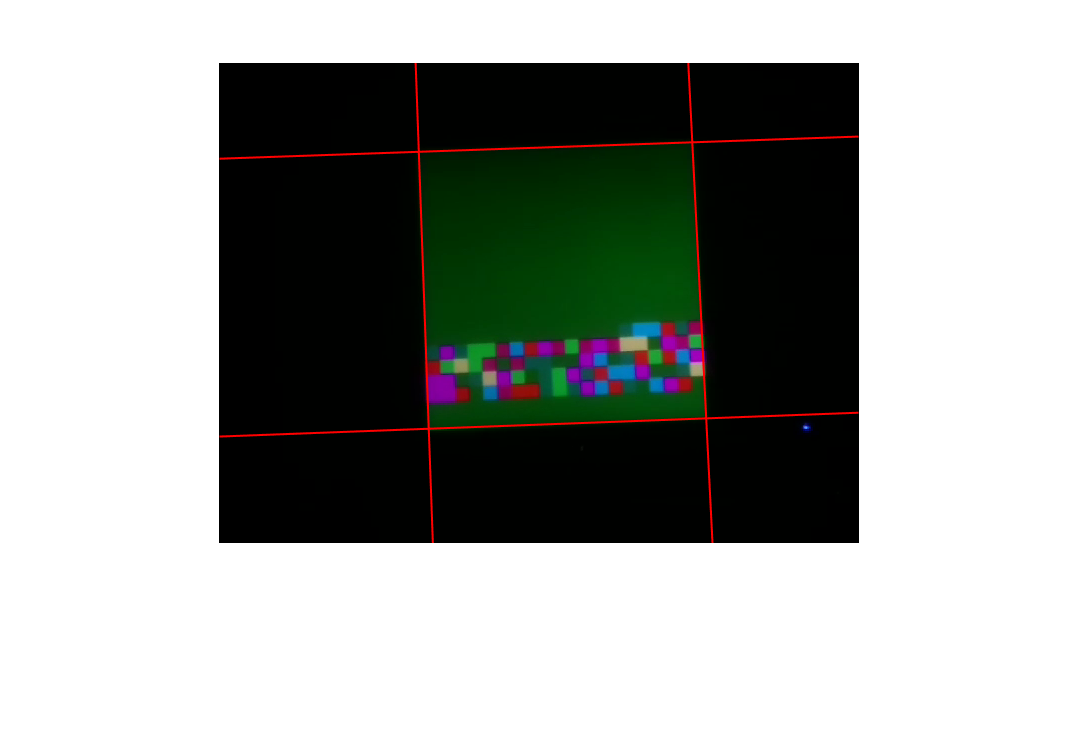

lookupTable =      0   144    44
     0   164   111
     0   255    85
   255   242   150
   255     0   255
     0   228   245
   225     0   128
   255     0     0


receivedBitStreamNoML = demodNoML(data,i,20,net1.DirtyValidNet);

% Check accuracy of demodulation 
sent = '250641451005016233665145306720402167256431267142312711471004250233667553100675461005215031220101310731453347216534462563100675461005155031271154336615531004415733066545346064123047444024664562100405623506416534420103336671413342010433674554312064121202146115220151334201573527104034662562322625631006117110051551344201013447215035271040206675563026704021067571330624510320501502441557340745623226355035020154302735631006056231220143320605563166455631620141330660403367314534420164320624403566756233062056100411451007156534462440350674403066414530665440350641450320514333670171344645473207204033140161260146132165064141736440677142606621415142240221371563614412670014410175312724313027356310063157344201713367256210061557352671643447444030462546336711451006215735667154336605443226714710067562100711453106456335071151304725643226714703205164320645631006756210060556362201573506414534420120344675523126156410043565350625563046256231620145204675573262701502406412250641513462015031260544312710403466415735266144100611451007215031220146322711633502016432064556316201633126255610073550312670403546454535664556316201643206456310050162336651453067201502443565350625563046256231620146322661451342004024066145302715451006215710067157350201623126655735462440322720561002010433620156336104573232431043654504670430034344460124707445153011120313161567304327004436157211722335020143320605563166244033671040312621513502016432062415024641453026214534420167322721503367256410073562322721643126704034062562332645633466455733427015024064122406614530271545100711453026204035064145100211543126354133020163332605543302016034464556350260421006055631020157350641453442015133463157344665413506455733420141304675653502016432062415024625023366755310060556310201203446755231261564100435653506255630462562316201413502016432062440304675643506755510067546100721503227144031464554312270401004455630666165310625441006456303205151332701573447214133472040322671463367115530272151336670403027471023152032045555230122705302203125700316662340432317374363233673145373375664605230304675653502017133672562100715603126155131464543100711513166416434620141334620403446256335071151306721513366716310064556032051503367344035064145100631513306244033260571100611451007256331262056100201313367244030660556100605543466744031464556310201573527204030261157352720403206756710072157100665413266244030206412310675563027215133667040350674402407115732462543350201073527214533461145344634541006055631020150336734403506744031662564100645563546755435462544134064120320501502425052256625543066755531220124336201243206244025667562330620403366304021471145312201203306055133420126302671513306614110051514212636772457744104207264654753561345034712223663743163436642565537160754353466712126614530672162336671513062012431274164346250520320501502425052312411573366556310051145302621413046614510041171100411573506404022072555302671631006055631020102362201033366656035272145344714541005155133461545100304711563045212406412032050521242505212452150312715451006250233667553346201273127114510050162312701413446254410041171100521503367256330267144346201573142012633666165334721453127116310225052124250520320501502406412250645643306247210052150312201013107314533472165344625631006754610051550312711543366155310044157330665453460641203205101352721503367107210051551344201013447215035271040206532503501773214704045641444274311672275763343754175607552633663564627040054626575746633667141334201043367455431206412032051223126614530271545100421413506247210046541344615501302006116234471100201332124115733665440106304661543053503205133232675633502016231261545334721543622016534062141350625441642011633673145332611453442006216226040144300601445641502406412212621513506455733435040142310150240641223060556316725413166247210042556316661513466401502406412206641413446054335062562100715453502014533461557310645563163504020251503222444150240641212425052100515242025112410047506100521102122012024447512212415241004352525042516204425222162010520447517226260402504410510040504254425162511541476671674641064406365742034527764254512436320316067473350532161232223765715236636252511052462011721420123220425222304750322620110236461152125144012425052032050150240000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000155716141226574626463304627232606110045017275444013420124175540013447056771214571054700000000000000000000000000000000000000000';

temp = str2mat(sent);
sent2 = [];
for u = 1:length(temp)
    sent2 = [sent2, str2double(temp(u))];
end


temp = str2mat(receivedBitStreamML);
receivedBitStreamML2 = [];
for u = 1:length(temp)
    receivedBitStreamML2 = [receivedBitStreamML2, str2double(temp(u))];
end

[a b c] = symerr(receivedBitStreamML2,sent2);
accML = 100 - b*100

accML = 90.2083


[a b c] = symerr(receivedBitStreamNoML,sent2);
accNoML = 100 - b*100

accNoML = 47.1875


disp("Machine Learning offers " + string(accML-accNoML) + "% improvement in performance")

Machine Learning offers 43.0208% improvement in performance


% find which symbol error per frame (ML)
rec = convertStringsToChars(receivedBitStreamML);
for i = 1:12
    count = 0;
    for j = 1:400
        if sent((i-1)*400+j) == rec((i-1)*400+j)
            count = count +1;
        end
    end
    count
end

count = 351

count = 360

count = 355

count = 353

count = 349

count = 352

count = 365

count = 354

count = 365

count = 351

count = 377

count = 398

% symbols = image2symbols(cell2mat(data(1)),net1.DirtyValidNet,20);
% ans = {1,400};
% for row = 1:20
%     for col = 1:20
%         img = cell2mat(symbols(row,col));
%         ans{} =  predict(net2.trainedNet,img);
%     end
% end

confusionchart(sent2',receivedBitStreamNoML')
% for i = 1:12
%     imwrite(cell2mat(data(i)),'Temp\'+string(i)+'.jpg');
% end

function receivedBitStream = demodML(data,i,net1,net2,numSymbols)
    receivedBitStream = "";
    for k = 1:i-1
        img = cell2mat(data(k));
        symbols = image2symbols(img,net1,numSymbols);
            for row = 1:numSymbols
               for col = 1:numSymbols
                   img = cell2mat(symbols(row,col));
                   symbol = classify(net2,img);
                   receivedBitStream = receivedBitStream+string(symbol);
               end
            end 
    end
end

function rec = demodNoML(data,i,numSymbols,net)
    rec = [];
    lookupTable  = [0,144,44 ; 0,164,111 ; 0,255,85 ; 255,242,150 ; 255,0,255 ; 0,228,245 ; 225,0,128 ; 255,0,0];
    for k = 1:i-1
        symbols = image2symbols(cell2mat(data(k)),net,numSymbols); %convert captured images to symbols
        RGBsym = symbol2RGB(symbols,numSymbols);     % convert symbols to an average RGB value
        for j = 1:numSymbols*numSymbols    
            lst  = [];
            foundPoints = cell2mat(RGBsym(j));
            for w = 1:length(lookupTable)
                lst = [lst , norm(lookupTable(w,:) - foundPoints)];
            end
            NN = find(lst == min(lst));  % find nearest neighbour from 8 choices
            rec = [rec, NN];
        end
        end
      rec = rec - 1;
end

function [RGBcell] = symbol2RGB(symbols,numSymbols)
    RGBcell = {1,numSymbols*numSymbols};
    temp = zeros(1, 3);
    y = 1;
    for row = 1:numSymbols
        for col = 1:numSymbols
            oneSymbol = cell2mat(symbols(row,col));

    %         meanR = mean2(oneSymbol(:,:,1));
    %         meanG = mean2(oneSymbol(:,:,2));
    %         meanB = mean2(oneSymbol(:,:,3));
             
            temp(:,1) = mean2(oneSymbol(9:15,8:24,1)); % mean R
            temp(:,2) = mean2(oneSymbol(9:15,8:24,2)); % mean G
            temp(:,3) = mean2(oneSymbol(9:15,8:24,3)); % mean B
%
            RGBcell{y} = temp;
            y = y + 1;

        end
    end
end